Theory: in proportional expression mode it is better to have the stoichiometry of the enzyme secretion reaction (enzyme:biomass_pseudo) to be a/(1-a):1 than a:(1-a). This leaves the ratio of biomass_pseudo to glc influx and actual growth consistent regardless of alpha.

This file is intended to demonstrate that the two get different results.

Note that buildSpeciesModel does not change which is designated as the biomass reaction

%Create and run a COMETS sim that uses the version included in the normal factory function
%that is, a/(1-a):1

v = getOptVars();

v_default = v;


load('C:\sync\biomes\models\Scerevisiae_iMM904.mat');
model = buildScerevisiaeModel(v,model,'testModel',v.mode);


layout = buildCelOptLayout(model);


runComets(layout)

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


ans =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script

media = parseMediaLog(layout.params.mediaLogName);
biomass = parseBiomassLog(layout.params.biomassLogName);

media1 = media;
biomass1 = biomass;

plot(biomass.biomass,'LineWidth',2);

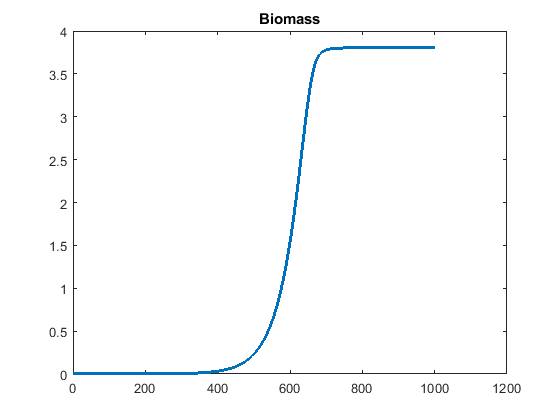

title('Biomass');


plotMediaTimecourse(media,{'glc__D_e' 'enzyme_e' 'cellulose'})

ans =   3×1 Line array:

  Line    (glc__D_e)
  Line    (enzyme_e)
  Line    (cellulose)

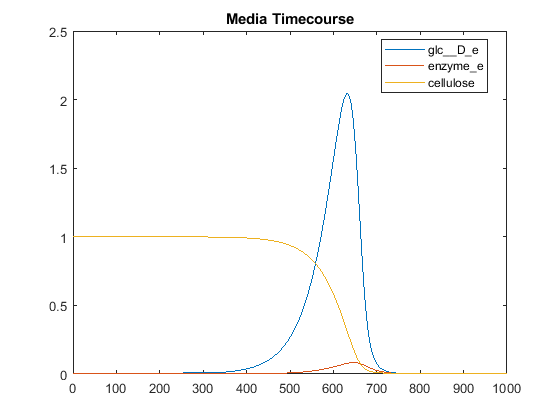

title('Media Timecourse');

%modify the model to use stoich a:(1-a)
model = layout.models{1};
ridx = stridx('secrete_enzyme',model.rxns);
find(model.S(:,ridx))

ans =         1227
        1228
        1229

model.mets(find(model.S(:,ridx)))

ans = 3×1 cell array
    {'biomass_pseudo'}
    {'enzyme_c'      }
    {'enzyme_e'      }

model.S(1227,ridx) = -(1-v.alpha);
model.S(1228,ridx) = -v.alpha;
model.S(1229,ridx) = v.alpha;
layout.models{1} = model;

runComets(layout)

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


ans =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script

media = parseMediaLog(layout.params.mediaLogName);
biomass = parseBiomassLog(layout.params.biomassLogName);

media2 = media;
biomass2 = biomass;

plot(biomass2.biomass,'LineWidth',2);
title('Biomass 2');


plotMediaTimecourse(media2,{'glc__D_e' 'enzyme_e' 'cellulose'})

ans =   3×1 Line array:

  Line    (glc__D_e)
  Line    (enzyme_e)
  Line    (cellulose)

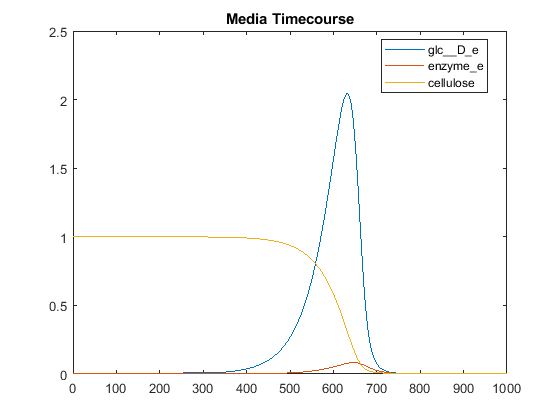

title('Media Timecourse 2');

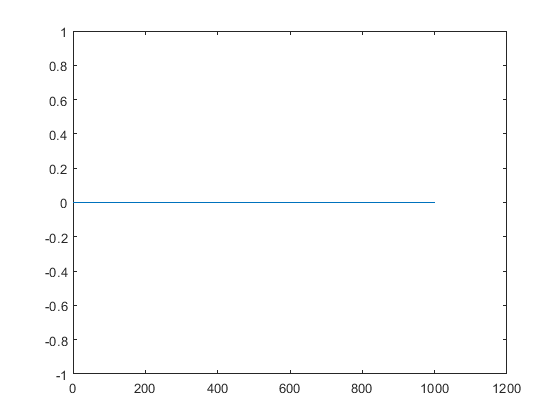

%is there a difference in biomasses?
plot(biomass.biomass - biomass2.biomass)

find(biomass.biomass - biomass2.biomass)

ans =
  0×1 empty double column vector
